**ACTIVIDAD 3 (EVALUACIÓN)**

**INTEGRANTES:**

A01735217 - Diego García Rueda

**Obtener  ** el vector de velocidades lineales y el vector de velocidades angulares para los siguientes robots manipuladores:

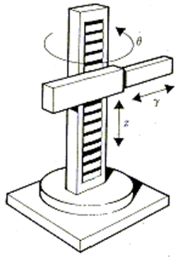

**MARCO DE REFERNCIA:**

Para este desarrollo se usará el siguiente marco de referencia, este sera al mismo a la primera junta rotacional, el marco se presenta a continuación:

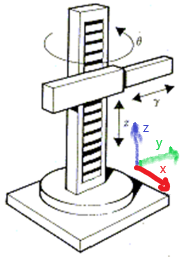

**DESARROLLO DE LA ACTIVIDAD:**

Se usan comandos de limpieza de *workspace*

clear all
close all 
clc

Se crean las variables simbolicas que se usaran para el analisis del robot articular. Estas representan la longitud de las juntasm, y en el caso de la junta rotacional su angulo de giro.

syms th1(t) l1 l2(t) l3(t) t

Se establece la configuración del robot, en este caso la primera junta es rotacional mientrass que las otras 2 son prismaticas.

RP=[0 1 1];

Se crea un vector de coordenadas articulares. Posteriormente este vector es derivado para obtener un vector de velocidades articulares.

Q = [th1, l2, l3];
Qp = diff(Q, t);

Se establece el número de los Grados De Libertad (GDL)  tanto como valor numerico como dato de tipo *String *

GDL= size(RP,2); 
GDL_str= num2str(GDL);

***ARTICULACIÓN 1***

Se crea el vector de traslación de la junta 1 respecto a la 0. El vector de posición se encuentra unicamente en los ejes X y Y debido a que al rotar en el eje Z solo hay desplazamiento en estos 2 ejes. 

Se crea también la matriz de rotación que evaluara la rotación de la siguiente junta respecto a la junta anterior. En este caso no es necesario hacer ninguna transofrmacion debido a que la junta 2 (prismatica ya se encuentra también posicionada de la manera correcta respecto al marco de referencia). En este caso se usa una matriz identidad.

Ambos valores se guardan en la página 1.

P(:,:,1)= [l1*cos(th1); l1*sin(th1); 0];

R(:,:,1)= [1 0 0;
           0 1 0;
           0 0 1];

***ARTICULACIÓN 2***

Se crea el vector de traslación de la junta 2. Al ser una junta prismatica solamente se desplaza en un eje (en este caso se coloco que el desplazamiento sea en el eje Z, ´pero puede colocar este valor en cualquier eje). 

Se crea también la matriz de rotación que evaluara la rotación de la siguiente junta respecto a la junta posterior(-90° en el eje X, se usa la matriz de rotación de este eje evaluada en estos grados, sin(-90) = 1). 

Ambos valores se guardan en la página 2.

P(:,:,2)= [0; 0; l2];
R(:,:,2)= [1 0 0;
           0 0 1;
           0 -1 0];

***ARTICULACIÓN 3***

Se crea el vector de traslación de la junta 3. Al ser una junta prismatica solamente se desplaza en un eje (en este caso se coloco que el desplazamiento sea en el eje Z, ´pero puede colocar este valor en cualquier eje). 

Finalmente en la matriz de rotación se usa una matriz identidad ya que al ser la última junta no afecta a una junta posterior. 

Ambos valores se guardan en la página 3.

P(:,:,3)= [0; 0; l3];
R(:,:,3)= [1 0 0;
           0 1 0;
           0 0 1];

**CREACIÓN DE MATRICES GLOBALES Y LOCALES**

Se crea un vector de ceros, Este vector se usa para "completar" las matrices homogéneas locales y globales, este vector permite que esta matriz sea una matriz cuadrada. 

Vector_Zeros= zeros(1, 3);

Se inicializan las matrices de transformacion locales y global usando los vectores de traslación y las matrices de rotación. Para realizar las matrices cuadradas se agrega el vector de ceros.

A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

Se inicializan los valores de los vectores de posición y de rotación (vistos desde el marco de referencia inercial).

PO(:,:,GDL)= P(:,:,GDL); 
RO(:,:,GDL)= R(:,:,GDL);

Se realiza un ciclo *for * en el que usando los Grados De LIbertad (GDL) como iterador. Usando este iterador se van creando las matrices locales de cada junta. 

Posteriormente se vn creando las matrices de transformación globales. Aqui existen 2 casos en los que se pueden generar estas matrices:

- Caso #1: Solo hay 1 GDL por lo que la matriz global es igual a la matriz de transformación local de esa junta.

- Caso #2: Hay más de 1 GDL, en eset caso, la matriz global se genera al multiplicar la matriz global anterior (es decir, de la articulacion anterior) por la matriz local actual (de la articulación actual) generando asi la nueva matriz de tranformación global, esto es asi debido a que con cada Matriz de transformación local se modifica la matriz global.

Obtenemos la matriz de rotación (RO) y el vector de traslación (PO) a partir de la Matriz de Transformación Homogénea Global en paginas diferentes.

for i = 1:GDL
    i_str= num2str(i);
    %Matrices Locales
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    
    %Matrices Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);  % GDL == 1
    end

    T(:,:,i)= simplify(T(:,:,i));

    %Da la matriz de rotacion de la matriz global
    RO(:,:,i)= T(1:3,1:3,i);
    %Da el vector de traslación de la matriz global
    PO(:,:,i)= T(1:3,4,i);

end

**CALCULO DE JACOBIANOS**

**Método de diferenciación:**

Primero obtenemos el Jacobiano Lineal usando el método de diferenciación. Se realizan derivadas parciales respecto a x, y, z obteniendo asi 9 derivadas parciales. Para esto se usan los vectores de posición.

Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), l2);
Jv13= functionalDerivative(PO(1,1,GDL), l3);

Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), l2);
Jv23= functionalDerivative(PO(2,1,GDL), l3);

Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), l2);
Jv33= functionalDerivative(PO(3,1,GDL), l3);

Se crea la matriz del Jacobiano lineal.

jv_d=simplify([Jv11 Jv12 Jv13; Jv21 Jv22 Jv23; Jv31 Jv32 Jv33]);

**FUNCIÓN *****calculo_analitico_Jacobianos:***

Esta función unicamente es un ciclo *for *que usa como parametro la configuración del robot (RP). 

En la sección de *try * se encuentran las formulas del Jacobiano Lineal Analiticoo y del Jacobiano Angular Analitico respectivamente.

En la sección de *catch* se encuentran las formulas para los Jacobianos en caso de que solo haya 1 GDL, debido a que no tenemos articulaciones previas usando asi una matriz identidad. Esta función se puede encontrar en el archivo  ***calculo_analitica_Jacobianos.m ****en el repositorio.*

**Método Análitico:**

Se inicializan los Jacobianos Análiticos (Lineal y Angular). Para esto se utiliza una funcion llamada *calculo_analitico_Jacobianos *quedando de la siguiente manera:

[Jv_a, Jw_a] = calculo_analitico_Jacobianos(PO, RO, RP, GDL);

Se simplifican los Jacobianos obtenidos:

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);

Se mandan a imprimir las velocidades lineal y angular obtenidas usando sus Jacobianos correspondientes diferenciandolos.

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

-- --   _________
|  |     d
|  |  - -- th1(t) (l3(t) + l1
-- --   dt

                --
                 |
   sin(th1(t)))  |,
                --

  -- ________      _________
  |   d             d
  |  -- l3(t) + l1 -- th1(t)
  -- dt            dt

               --
                |
   cos(th1(t))  |,
               --

  -- ________ -- --
  |   d        |  |
  |  -- l2(t)  |  |
  -- dt       -- --



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



**ANALISIS DE MOVIMIENTO **

**Velocidad lineal: **

En el eje X no hay velocidad lineal, unicamente angular, esto es la derivada del angulo (th1), en este eje no hay desplazamiento linear, solamente rotaciones. 

En el eje Y hay velocidad lineal, ya que es la derivada de la posicion lineal (l3).

En el eje Z hay velocidad lineal, ya que es la derivada de la posicion lineal (l2).

**Velocidad angular:**

Unicamente hay velocidad angular en el eje Z debido ya que es en este eje en el que ocurre la rotación del robot articular.